%% PCA on concatenated beta-band EEG, then time & frequency plots of PCs
clear; close all;

% --- paths (use your original logic) ---
if exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

conditions = {'BLA'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load


% Concatenate beta-band filtered data across conditions and trials:
beta_concat = [];        % will be channels x totalSamples
trial_ranges = [];       % Nx2 start/end indices in concatenated samples
trial_info = {};         % optional: store [condition, trialIndexInCondition]

for ci = 1:numel(conditions)
    condition = conditions{ci};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    if isempty(set_files)
        fprintf('No .set files for %s — skipping\n', condition);
        continue
    end
    % load first subject/file (you used set_files(1).name)
    EEG = pop_loadset(fullfile(in_dir, set_files(1).name));
    if isempty(fs), fs = EEG.srate; end

    % choose odd/even indexing as in your pipeline
    if ismember(condition, {'BLA','P1','P2','P3'})
        epoch_trials = 1:2:EEG.trials;
    else
        epoch_trials = 2:2:EEG.trials;
    end

    data = EEG.data(:, :, epoch_trials); % channels x time x trials
    nTrials = size(data,3);
    nTime = size(data,2);

    % preallocate and bandpass each epoch (Signal Processing Toolbox bandpass)
    beta_band = [13 30];
    beta_local = zeros(size(data));
    for tr = 1:nTrials
        % bandpass expects samples x 1 or samples x channels -> transpose
        beta_local(:,:,tr) = bandpass(squeeze(data(:,:,tr))', beta_band, fs)'; 
    end

    % reshape: channels x (time * trials)
    resh = reshape(beta_local, num_ch, nTime * nTrials);

    % append to concatenated matrix
    startIdx = size(beta_concat,2) + 1;
    beta_concat = [beta_concat, resh];
    endIdx = size(beta_concat,2);

    % store trial boundaries (assumes contiguous blocks of length nTime)
    for tr = 1:nTrials
        s = startIdx + (tr-1)*nTime;
        e = s + nTime - 1;
        trial_ranges = [trial_ranges; s e];
        trial_info{end+1} = struct('condition',condition,'trialInCond',tr);
    end
end

pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...



fprintf('Concatenated size: channels x samples = %d x %d\n', size(beta_concat,1), size(beta_concat,2));

Concatenated size: channels x samples = 32 x 107520


% --- PCA: rows = observations (samples), columns = variables (channels) ---
X = beta_concat';  % samples x channels

% reshape: channels x (time * trials)
data_resh = reshape(data, num_ch, nTime * nTrials);
X_unfilt = data_resh';
% Perform PCA (mean-centering done internally). Ask for as many PCs as channels.
[coeff, score, latent, tsquared, explained, mu] = pca(X_unfilt);  % coeff: channels x PCs


% Choose number of PCs: either fixed (e.g., 5) or by cumulative explained variance
target_n_pcs = 5;
cumExpl = cumsum(explained);
pcs_for_85 = find(cumExpl >= 85, 1, 'first');  % if you want 85% threshold

nPCs = min(target_n_pcs, size(coeff,2));
fprintf('Explained by first %d PCs: %.2f%%\n', nPCs, sum(explained(1:nPCs)));

Explained by first 5 PCs: 67.73%


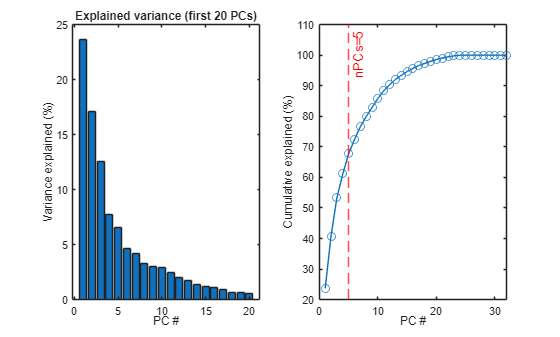


% Plot explained variance
figure;
subplot(1,2,1);
bar(explained(1:20));
xlabel('PC #'); ylabel('Variance explained (%)');
title('Explained variance (first 20 PCs)');
subplot(1,2,2);
plot(cumExpl,'-o'); xlabel('PC #'); ylabel('Cumulative explained (%)');
xline(nPCs, '--r', sprintf('nPCs=%d', nPCs));

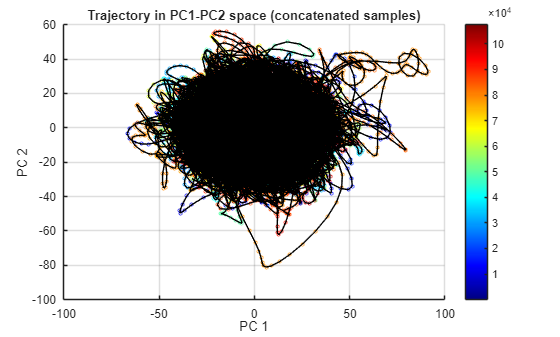

% ----------------------------
% 2D plot of top 2 PCs (trajectory in PC space)
% ----------------------------
figure('Name','Top-2 PC Phase-Space');
% Plot continuous trajectory coloured by time
T = size(score,1);
cmap = jet(T);
scatter(score(:,1), score(:,2), 6, linspace(1,T,T)); hold on;
plot(score(:,1), score(:,2), 'k-', 'LineWidth', 0.5); % trajectory line
xlabel('PC 1'); ylabel('PC 2');
title('Trajectory in PC1-PC2 space (concatenated samples)');
colorbar; colormap(jet);
grid on;

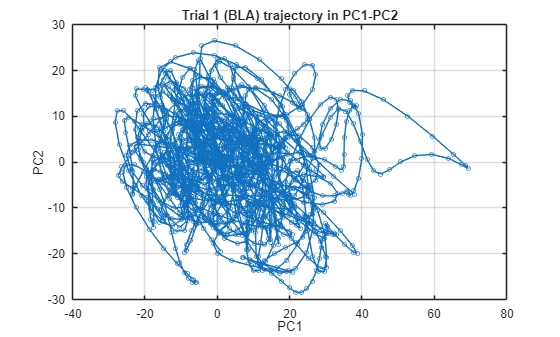


% Optionally highlight a single trial's trajectory (example: first trial)
example_trial_idx = 1;
s = trial_ranges(example_trial_idx,1);
e = trial_ranges(example_trial_idx,2);
figure('Name','Single-trial PC1 vs PC2');
plot(score(s:e,1), score(s:e,2), '-o','MarkerSize',3);
xlabel('PC1'); ylabel('PC2');
title(sprintf('Trial %d (%s) trajectory in PC1-PC2', example_trial_idx, trial_info{example_trial_idx}.condition));
grid on;

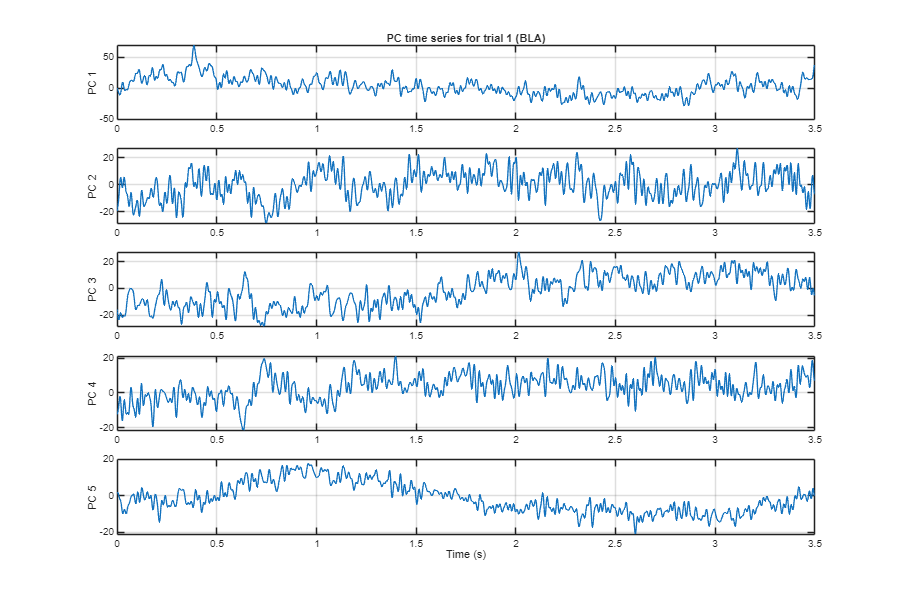

% ----------------------------
% Time-domain plots for top N PCs for a chosen trial
% ----------------------------
trial_to_plot = 1; % choose which trial to inspect
s = trial_ranges(trial_to_plot,1); e = trial_ranges(trial_to_plot,2);
tvec = (0:(e-s)) / fs;

scores_trial = score(s:e, 1:nPCs); % samples x nPCs

figure('Name','Top PCs - Time Domain','Position',[100 100 900 600]);
for p = 1:nPCs
    subplot(nPCs,1,p);
    plot(tvec, scores_trial(:,p), 'LineWidth', 1);
    ylabel(sprintf('PC %d', p));
    if p==1, title(sprintf('PC time series for trial %d (%s)', trial_to_plot, trial_info{trial_to_plot}.condition)); end
    if p==nPCs, xlabel('Time (s)'); end
    grid on;
end

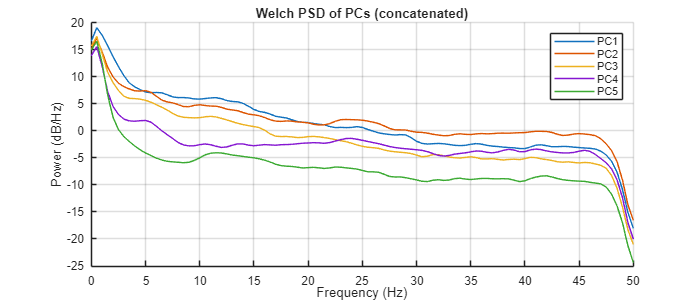

% ----------------------------
% Frequency-domain (Welch) for selected PCs
% ----------------------------
% Use full concatenated PC time-series or per-trial PC time series
pc_indices = 1:nPCs;
win = hamming(512);
noverlap = round(0.5*length(win));
nfft = 1024;

figure('Name','PC Power Spectra (Welch)','Position',[150 150 700 300]);
hold on;
for p = pc_indices
    [Pxx,f] = pwelch(score(:,p), win, noverlap, nfft, fs);
    plot(f, 10*log10(Pxx)); % dB scale
end
legend(arrayfun(@(x) sprintf('PC%d',x), pc_indices,'uni',false));
xlim([0 50]);
xlabel('Frequency (Hz)'); ylabel('Power (dB/Hz)');
title('Welch PSD of PCs (concatenated)'); grid on;

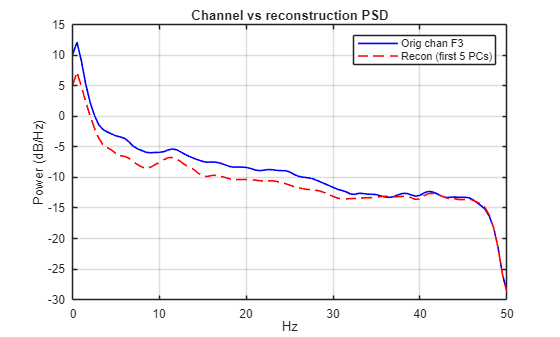


% Also compare to an example raw channel's PSD (channel 6)
example_chan = 6;
figure('Name','Channel vs Reconstructed (PC-based) PSD');
% Original channel PSD (concatenated)
[Px_chan, fchan] = pwelch(X_unfilt(:,example_chan)', win, noverlap, nfft, fs);
% PSD from reconstructed signal using first nPCs for that channel:
% reconstruct channel time series: X_recon = score(:,1:nPCs) * coeff(channel,1:nPCs)' + mu(channel)
recon_chan = score(:,1:nPCs) * coeff(example_chan,1:nPCs)' + mu(example_chan);
[Px_recon, frecon] = pwelch(recon_chan, win, noverlap, nfft, fs);
plot(fchan, 10*log10(Px_chan), 'b', 'LineWidth',1.2); hold on;
plot(frecon,10*log10(Px_recon),'r--','LineWidth',1.2);
legend(sprintf('Orig chan %s', EEG.chanlocs(6).labels), sprintf('Recon (first %d PCs)', nPCs));
xlim([0 50]); xlabel('Hz'); ylabel('Power (dB/Hz)'); title('Channel vs reconstruction PSD'); grid on;

% ----------------------------
% How to choose 3 PCs "around the median explained variance"
% ----------------------------
% explained is a vector per-PC in descending order.
median_expl = median(explained);
[~, idx_sorted_by_dist] = sort(abs(explained - median_expl)); % distance to median explained
three_near_median = idx_sorted_by_dist(1:3);
fprintf('Three PCs closest to median explained variance: [%s]\n', sprintf('%d ', three_near_median));

Three PCs closest to median explained variance: [16 17 15 ]


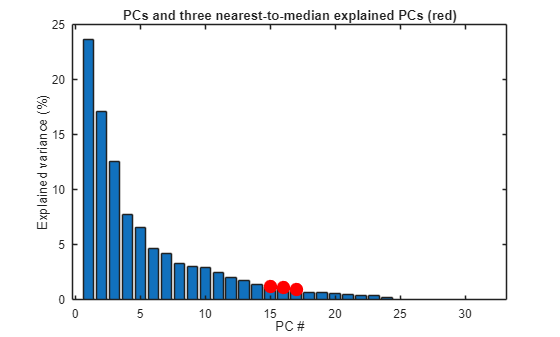


% OPTIONAL: visualize which PCs these are on the explained bar plot (overlay)
figure;
bar(explained);
hold on;
scatter(three_near_median, explained(three_near_median), 100, 'r', 'filled');
xlabel('PC #'); ylabel('Explained variance (%)');
title('PCs and three nearest-to-median explained PCs (red)');


% Save variables if you want
save(fullfile(output_path,'pca_results.mat'),'coeff','score','explained','mu','trial_ranges','trial_info');

fprintf('Done. nPCs used: %d. Three PCs near median: %s\n', nPCs, mat2str(three_near_median));

Done. nPCs used: 5. Three PCs near median: [16;17;15]


figure('Name','PC Power Spectra (Welch)','Position',[150 150 900 500]);
hold on;
for p = three_near_median
    [Pxx,f] = pwelch(score(:,p), win, noverlap, nfft, fs);
    plot(f, 10*log10(Pxx)); % dB scale
end
legend(arrayfun(@(x) sprintf('PC%d',x), pc_indices,'uni',false));

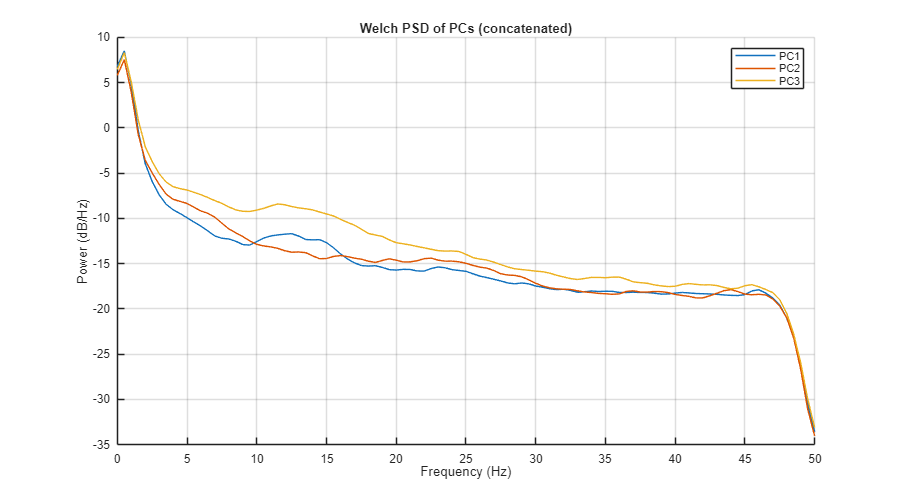

xlim([0 50]);
xlabel('Frequency (Hz)'); ylabel('Power (dB/Hz)');
title('Welch PSD of PCs (concatenated)'); grid on;